clc;
close all;

**3.1 Task 1**

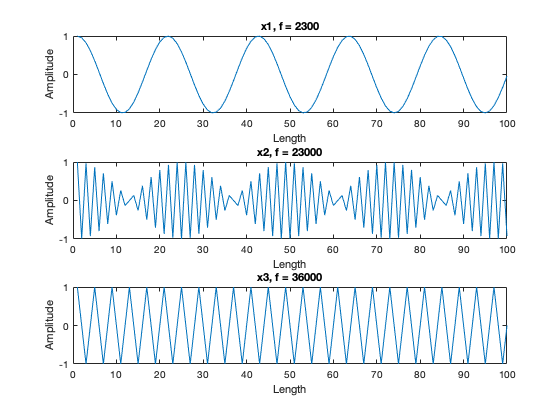

L  = 100;
Fs = 48000;

f1 = 2300;
f2 = 23000;
f3 = 36000;

x1 = generate_sigs(f1,Fs,L);
x2 = generate_sigs(f2,Fs,L);
x3 = generate_sigs(f3,Fs,L);

figure();
subplot(3,1,1); %(how many rows, how many col, index)
plot(x1)
title("x1, f = 2300")
xlabel("Length")
ylabel("Amplitude")

subplot(3,1,2);
plot(x2);
title("x2, f = 23000")
xlabel("Length")
ylabel("Amplitude")

subplot(3,1,3);
plot(x3);
title("x3, f = 36000")
xlabel("Length")
ylabel("Amplitude")

print -depsc epsTask1

**3.3 Task 2**

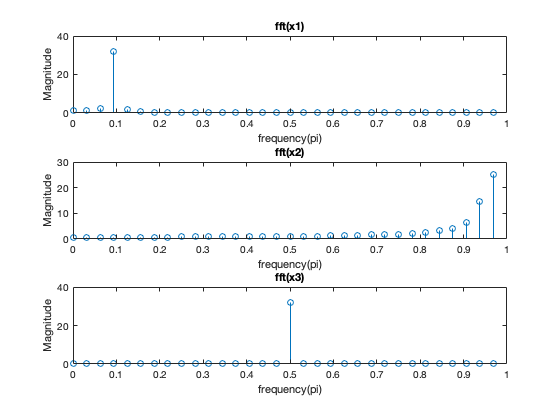

x1fft = fft(x1,64);
x2fft = fft(x2,64);
x3fft = fft(x3,64);

xAxis = 0:1/32:1-1/32; % now we have 32 sampl with 1/32 gap

figure();
subplot(3,1,1);
stem(xAxis,abs(x1fft(1:32)))
title("fft(x1)")
xlabel("frequency(pi)")
ylabel("Magnitude")

subplot(3,1,2);
stem(xAxis,abs(x2fft(1:32)));
title("fft(x2)")
xlabel("frequency(pi)")
ylabel("Magnitude")

subplot(3,1,3);
stem(xAxis,abs(x3fft(1:32)));
title("fft(x3)")
xlabel("frequency(pi)")
ylabel("Magnitude")

print -depsc epsTask2

**3.3 Task 5**

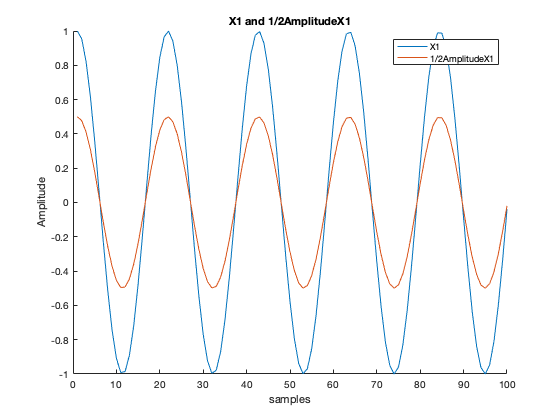

fileName1 = "x1AudioFile.wav";
fileName2 = "x2AudioFile.wav";
fileName3 = "x3AudioFile.wav";
audiowrite(fileName1,x1,Fs);
audiowrite(fileName2,x2,Fs);
audiowrite(fileName3,x3,Fs);

[y1,Fs] = audioread("x1output.wav");
figure();
hold on;
plot(x1);
plot(y1);
hold off;
title("X1 and 1/2AmplitudeX1")
xlabel("samples")
ylabel("Amplitude")
legend('X1','1/2AmplitudeX1')
print -depsc epsTask3

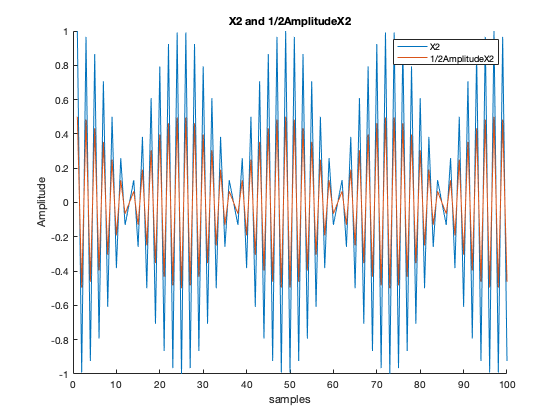


[y2,Fs] = audioread("x2output.wav");
figure();
hold on;
plot(x2);
plot(y2);
hold off;
title("X2 and 1/2AmplitudeX2")
xlabel("samples")
ylabel("Amplitude")
legend('X2','1/2AmplitudeX2')
print -depsc epsTask4

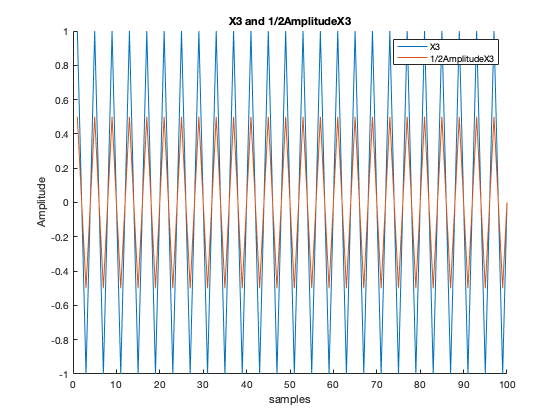


[y3,Fs] = audioread("x3output.wav");
figure();
hold on;
plot(x3);
plot(y3);
hold off;
title("X3 and 1/2AmplitudeX3")
xlabel("samples")
ylabel("Amplitude")
legend('X3','1/2AmplitudeX3')

print -depsc epsTask5

function x = generate_sigs(f,Fs,L)
    t = 0:1/Fs:L/Fs - 1/Fs ; 
    x = cos(2*pi*f*t); 
end